% esempio sistema del tipo 0
% errore di posizione
syms t
 n = 40;
 d = [1 6 45];
 G0 = tf(n,d)

G0 =
 
        40
  --------------
  s^2 + 6 s + 45
 
Continuous-time transfer function.



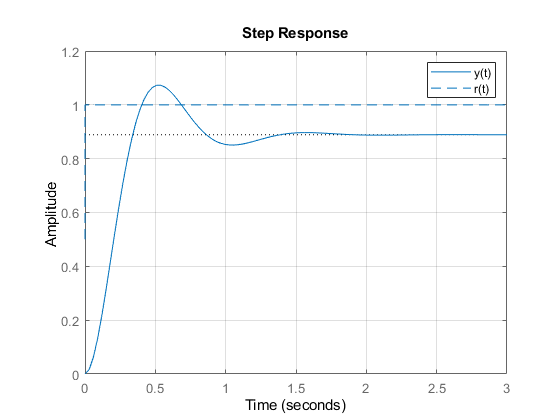

 figure(1)
 step(G0, 3), grid, hold on
 fplot(heaviside(t),'--'), legend('y(t)','r(t)') 

 % a regime ha un valore finito cosante e l'errore di posizione
 % è circa 0.1
 
 % cosa succede se vogliamo valutare l'errore di velocità
 % errore di velocità in risposta a una rampa unitaria
 s = tf('s') % il sistema è lo stesso

s =
 
  s
 
Continuous-time transfer function.



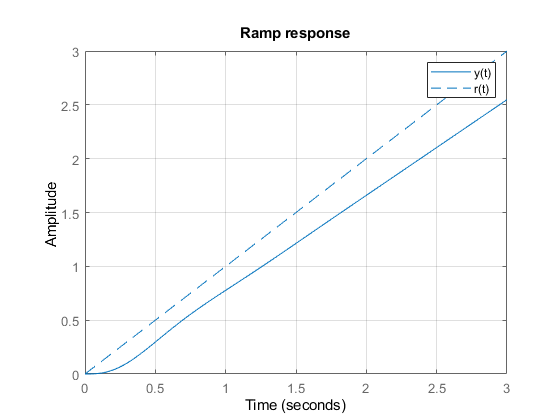

 figure(2)
 step(G0/s,3), grid, title('Ramp response');
 hold on
 fplot(t*heaviside(t),'--'), legend('y(t)','r(t)')

 % lo scarto a regime tra l'ingresso y(t) e l'uscita r(t) tende
 % a divergere a infinito e quindi l'errore di velocità 
 % risulta essere infinito, la stessa cosa vale per l'errore
 % di accelerazione
 % errore di accelerazione
 s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



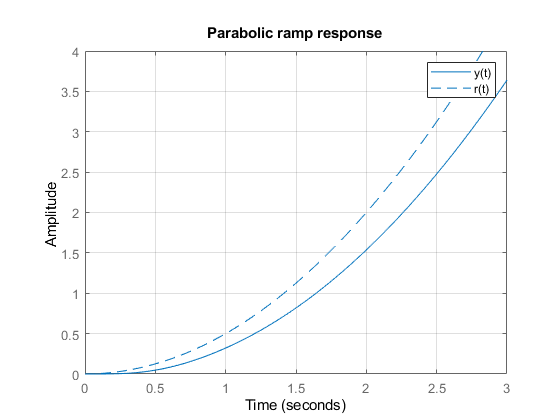

 figure(3)
 step(G0/s^2, 3), grid, title ('Parabolic ramp response')
 hold on
 fplot(t^2/2*heaviside(t),'--'), legend('y(t)','r(t)')